## **Non-linear Model Trajectory with Custom Track**


$$\dot x(t)=u(t) \cos \theta(t) - v(t) \sin \theta(t)$$



$$\dot y(t)=u(t) \sin \theta(t) + v(t) \cos \theta(t)$$



$$u(t)=cte$$



$$\dot{v}(t) = -\frac{c_f + c_r}{M u} v(t) + \frac{c_r c - c_f b - M u^2}{M u} r(t) + \frac{c_f}{M} \delta(t)$$



$$\dot{r}(t) = \frac{c c_r - b c_f}{u I} v(t) - \frac{c^2 c_r + b^2 c_f}{u I} r(t) + \frac{c_f b}{I} \delta(t)$$


theta dot = r 

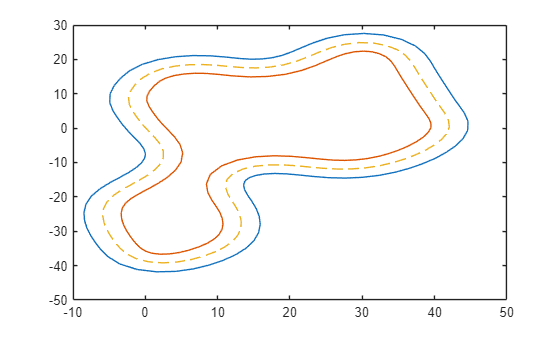

clc;clear;
%Define the track
track = load("circuitforalex.mat");
centerx = track.centers(:,1);
centery = track.centers(:,2);
innerx = track.Outx;
innery = track.Outy;
outx = track.Inx;
outy = track.Iny;
trackwidth = 4;

plot(track.Inx,track.Iny,track.Outx,track.Outy,track.centers(:,1),track.centers(:,2),'--')

d_seg = sqrt(diff(centerx).^2 + diff(centery).^2); %distance between each centerpoint
s_raw = [0; cumsum(d_seg)]; %circuit length in total
s_total = s_raw(end); 
N = 200;        % Fixed number of steps
s_step = linspace(0, s_total, N); 
ds = s_step(2) - s_step(1);

% B. Calculate Widths loop
W_left = zeros(N,1);
W_right = zeros(N,1);


for k = 1:N
    % Interpolate the specific coordinate on the centerline for this step
    % using 'centerx' and 'centery'
    xc = interp1(s_raw, centerx, s_step(k));
    yc = interp1(s_raw, centery, s_step(k));
    
    % d_left: Distance to Inner Island (innerx, innery)
    [d_left, ~, ~]  = p_poly_dist(xc, yc, innerx, innery);
    
    % d_right: Distance to Outer Wall (outx, outy)
    [d_right, ~, ~] = p_poly_dist(xc, yc, outx, outy);
    
    % Store absolute widths
    W_left(k) = abs(d_left);
    W_right(k) = abs(d_right);
end

[s_unique, idx_u] = unique(s_raw, 'stable');
cx_unique = centerx(idx_u);
cy_unique = centery(idx_u);

xref = interp1(s_unique, cx_unique, s_step, 'spline');
yref = interp1(s_unique, cy_unique, s_step, 'spline');

% Compute Reference Heading (psi_ref) and Curvature (kappa)
dx = gradient(xref, ds);   
ddx = gradient(dx, ds);
dy = gradient(yref, ds);   
ddy = gradient(dy, ds);
psi_ref = atan2(dy, dx); % Track Heading

kappa = (dx .* ddy - dy .* ddx) ./ (dx.^2 + dy.^2).^(1.5);

% Define the parameters for the vehicle dynamics
c_f = 70000; % Front tire cornering stiffness
c_r = 50000; % Rear tire cornering stiffness
M = 1500;   % Mass of the vehicle in kg
I = 3000;   % Moment of inertia
b = 1.5;    % Distance from the center of gravity to the front axle
c = 1.5;    % Distance from the center of gravity to the rear axle
L = b+c;    % Car Length 

%initial and final conditions
ui= 1;
uf= 1;
thetai= deg2rad(0);
thetaf= deg2rad(0);
vi=0;
ri=0;

%Time step size
T = 1;

yalmip('clear');

%Unknowns
v = sdpvar(N,1); %lateral velocity
r = sdpvar(N,1); %yaw rate
delta = sdpvar(N,1);
err_heading = sdpvar(N,1); %Heading Error [rad] (Angle diff between car and track)
u = sdpvar(N,1); % velocity as unknown
n = sdpvar(N, 1); % Lateral deviation variable
dt = sdpvar(N, 1);    % Time taken to travel segment k
ax = sdpvar(N,1); %acceleration

%Initial and final conditions
F = [n(1) == 0,... %start on centerline 
    err_heading(1) == 0, ... % start with heading error zero, theta=thetai
    u(1) == ui, ...     % Initial Speed
    n(N) == n(1),...    % End at same lateral position
    err_heading(N) == err_heading(1),...  % End with same heading alignment
    u(N) == uf]; %end velocity

% Objective func
obj = 0;%sum(delta.^2);  % sum of the squares of delta or V 

%Problem conditions loop
for k = 1:N-1
    k_ref = kappa(k); %get curvature
    % Time = Distance / Velocity
    step_T = ds / u(k);
    %lateral deviation (n)
    F = [F n(k+1) == n(k) + ds * (err_heading(k)+v(k)/u(k))]; 
    % Lateral Velocity (v)
    F = [F v(k+1) == v(k) + step_T* ... 
        (-(c_f + c_r)/(M*u(k)) * v(k) + (c_r*c - c_f*b - M*u(k)^2)/(M*u(k))* r(k) + c_f/M * delta(k))]; 
    %Yaw Rate (r)
    F = [F r(k+1) == r(k) + step_T*... 
        ((c*c_r - b*c_f)/(u(k)*I) * v(k) - (c^2*c_r + b^2*c_f)/(u(k)*I) * r(k)+ (c_f*b)/I * delta(k))];
    % Heading Error
    F = [F err_heading(k+1) == err_heading(k) + ds * (r(k) / u(k) - k_ref)];
    %maximum allowed speed change for each step
    F = [F u(k+1) == u(k) + step_T * ax(k)]; 

    F = [F abs(v(k+1)) <= 1]; 
    F = [F u(k+1) <= 40];
    F = [F u(k+1) >= 1];
    F = [F -0.7 <= delta(k)]; %steering angle 40 degrees 
    F = [F delta(k) <= 0.7]; 
    F = [F -W_right(k) <= n(k)];
    F = [F n(k) <= W_left(k)]; %TrackLimits - stay inside
    F = [F dt(k) * u(k) >= ds]; %time constraints
    F = [F -12 <= ax(k) ]; %acceleration limit 
    F = [F  ax(k) <= 8];
end


%Optimization options
options = sdpsettings('solver', 'ipopt', 'verbose', 0);
options.ipopt.constr_viol_tol = 1e-4;
options.ipopt.tol = 1e-4;              
options.ipopt.acceptable_tol = 1e-3;   % Even looser fallback tolerance
options.ipopt.max_iter = 2000;

% assign(u, 20 * ones(N,1));     % Guess speed = 20 m/s
% assign(n, zeros(N,1));         % Guess position = Centerline
% assign(err_heading, zeros(N,1));        % Guess heading = Aligned
% assign(delta, zeros(N,1));     % Guess steering = Straight

% Tell IPOPT to use these values
% options.ipopt.warm_start_init_point = 'yes';

optimization = optimize(F,obj,options);

if optimization.problem == 0 %|| optimization.problem == 4 
    fprintf('Feasible run\n')
    %saving the last solution to warm-start the new loops 
    sol_v = double(v);
    sol_r = double(r);
    sol_delta = double(delta);
    sol_err_heading = double(err_heading);
    sol_u = double(u);
    sol_n = double(n);      
else
    fprintf('Unfeasible run\n')
end

Feasible run


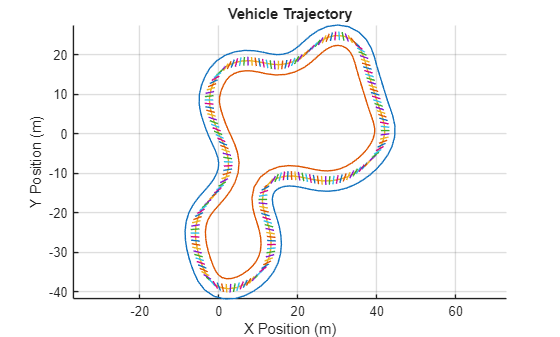

figure 
hold on
axis equal
grid on;
xlabel('X Position (m)');
ylabel('Y Position (m)'); 
title('Vehicle Trajectory');
sol_x = xref - sol_n .* sin(psi_ref);
sol_y = yref - sol_n .* cos(psi_ref);
plot(track.Inx,track.Iny,track.Outx,track.Outy,track.centers(:,1),track.centers(:,2),sol_x,sol_y)

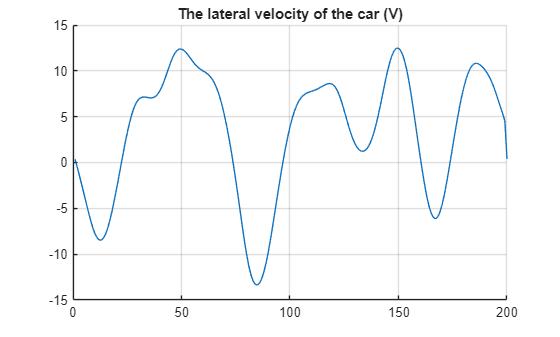


figure
hold on
%axis equal
grid on
title('The lateral velocity of the car (V)')
plot(sol_v*100/3.6)

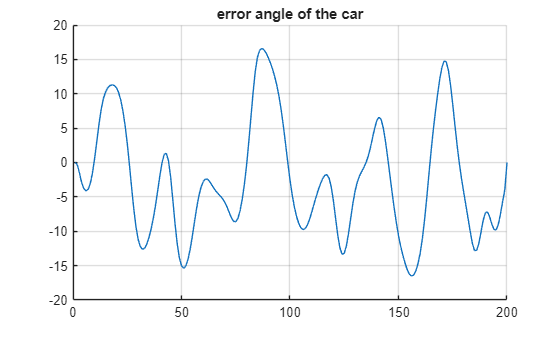


figure
hold on
%axis equal
grid on
title('error angle of the car')
plot(rad2deg(sol_err_heading))

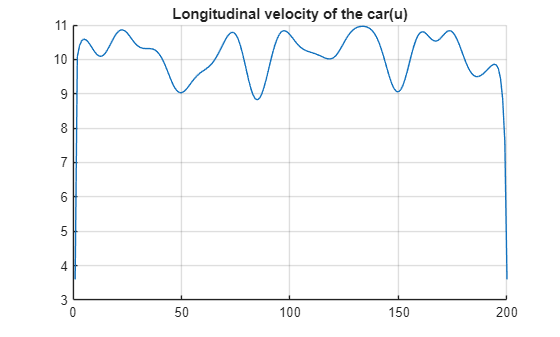

figure
hold on
%axis equal
grid on
title('Longitudinal velocity of the car(u)')
plot(sol_u*3.6)

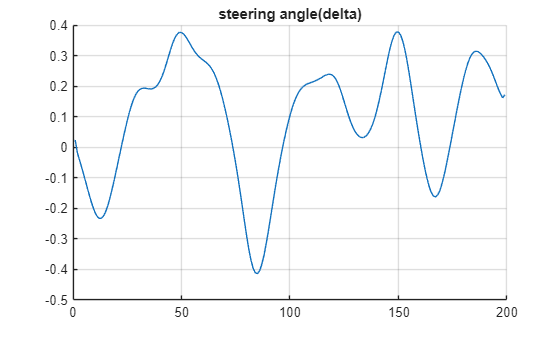


figure
hold on
grid on
title('steering angle(delta)')
plot(sol_delta)